## Treino para teste PL4

#### 1. Com base na função fft(.), desenvolva uma função no MATLAB/Octave, denominada Espetro, que retorna e apresenta o espetro (amplitude apenas) de um sinal (passado através do seu vetor de amostras, 𝐱) amostrado com período de amostragem 𝑇𝑎. O gráfico do espetro deve apresentar no eixo das abcissas a frequência em Hz, desde −𝑓𝑎/2 a +𝑓𝑎/2, onde 𝑓𝑎 = 1/𝑇𝑎. 

#### function [𝐗 , f] = 𝐸𝑠𝑝𝑒𝑡𝑟𝑜 ( 𝐱 , 𝑇𝑎 ) 

#### 𝐗 – vetor da mesma dimensão de 𝐱, com os coeficientes da DFT de 𝑥(𝑡).

#### 𝑓 – vetor da mesma dimensão de 𝐱, com as frequências (em Hz) de cada componente de 𝐗. 

%Espetro();

#### 2. Teste a função desenvolvida no ponto anterior, representando o espectro dos seguintes sinais: 

#### a) 𝑥(𝑡) = sin(2𝜋𝑡), registado durante 10 períodos. 

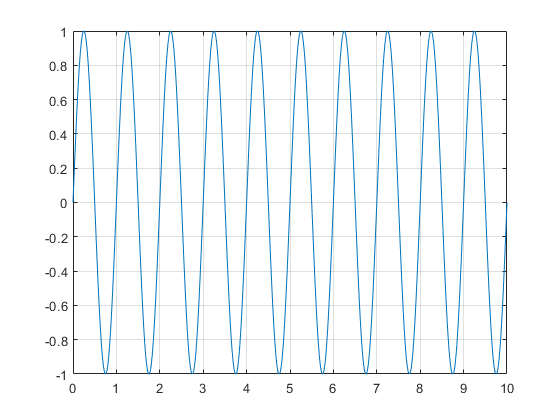

Ta = 0.001;
t = (0:Ta:10);
x = sin(2*pi.*t);
plot(t,x);
grid;

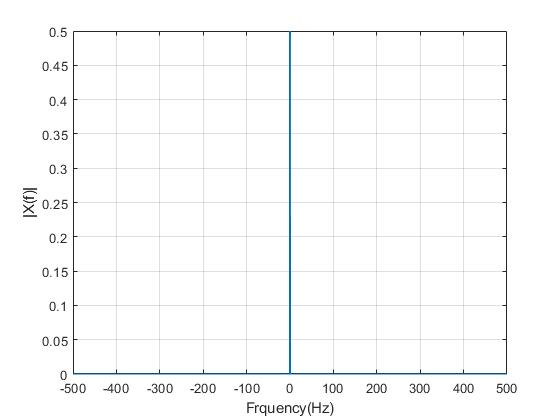

Espetro2(x,Ta);

#### b) 𝑦(𝑡) = sin(10𝜋𝑡) + cos(12𝜋𝑡) + cos(14𝜋𝑡 − 𝜋/4), registado durante 5 seg. 

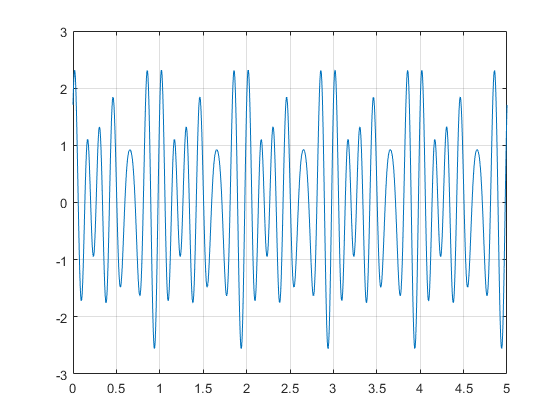

Ta = 0.001;
t = (0:Ta:5);
y = sin(10*pi.*t) + cos(12*pi.*t) + cos(14*pi.*t - pi/4);
plot(t,y);
grid;

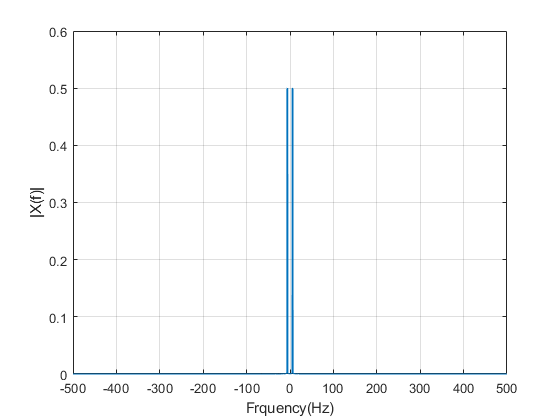

Espetro2(y,Ta);

#### c) 𝑧(𝑡) – onda quadrada entre 0 e 1, de frequência 1 Hz, registada durante 5 seg. 

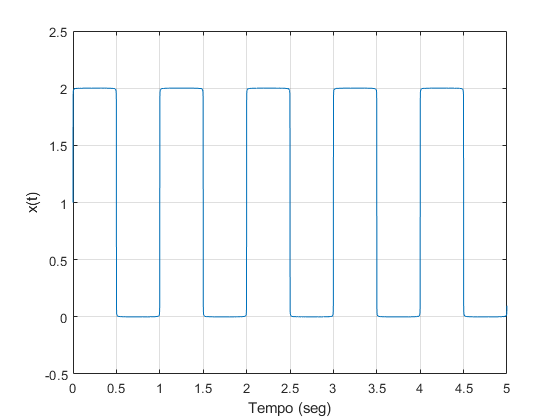

k = (1:998);
Ta = 0.001;
T = 1;
f0 = 1/T;
Np = 6;
ak = zeros(size(k));
bk = cos(2*pi.*k)./(pi.*k) - (2.*cos(pi.*k))./(pi.*k) + 1./(pi.*k);
[sinal,tempo] = Sinal_Fourier(Ta,f0,Np,ak,bk);
plot(tempo(1:(5/Ta)), sinal(1:(5/Ta))+1);
xlabel("Tempo (seg)");
ylabel("x(t)");
grid;

Espetro2(sinal(1:(5/Ta))+1,Ta);    

#### d) 𝑞(𝑡) - onda triangular entre -1 e 1, de frequência 1 Hz, registada durante 5 seg.

Ta = 0.001;
t = (0:Ta:5);
q = sawtooth(2*pi*1*t,1/2);
plot(t,q)
grid on
Espetro2(q,Ta);

#### 3. Acrescente a possibilidade de a função Espetro, desenvolvida na pergunta 1, poder implementar windowing, para analisar o conteúdo espetral de sequências de amostras não periódicas. Para tal, adicione um terceiro parâmetro de entrada, w, que, se for diferente de zero, aplica uma janela de Blackman à sequência de amostras antes de operar a fft.

#### 4. Teste a função da alínea anterior para criar o espetro de um sinal composto por: 

#### - 500 amostras; 

#### - período de amostragem igual a 1 ms; 

#### - o somatório de 20 sinais sinusoidais, cada um de amplitude unitária, cujas frequências são determinadas aleatoriamente entre 1 e 20 Hz (com distribuição de probabilidade uniforme); 

#### - a fase de cada sinusoide é também determinada aleatoriamente. Compare os espetros obtidos com e sem windowing

x  = zeros(1,500);
Ta = 0.001;
t = (0:499)*Ta;
A = 1;
fs = abs((20 - 1).*rand(1,20) + 1);
for i = 1:20
    x = sum((1*sin(2*pi.*fs(i)*t)));
end
plot(t,x,"-r");
Espetro2(x,Ta);
Espetro2(x,Ta,1);

#### 5. Desenvolva, agora, a função Reconstroi que efetua a operação inversa da função desenvolvida na pergunta 1 (i.e., recebendo o vetor 𝐗 da representação em Fourier, reconstrói a sequência de amostras do sinal no domínio do tempo, 𝐱, visualizando, depois, o sinal reconstruído). Teste a função com os dados obtidos nas perguntas anteriores.

%Reconstroi();

#### 6. Usando a função fft2, determine o espetro (bidimensional) da imagem formada pelas seguintes expressões. Interprete o espetro observado quando confrontado com a imagem visualizada de cada expressão. 

#### a) 𝑧(𝑥, 𝑦) = sin(2𝜋(2𝑥 + 𝑦)) , 𝑥, 𝑦 ∈ [−5; +5]. 

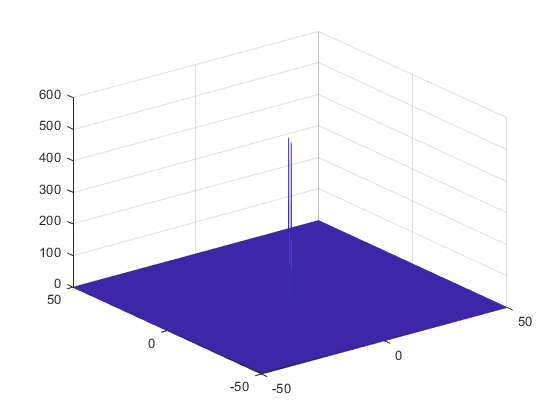

Ta = 0.01;
x  = (-5:Ta:5);
y  = (-5:Ta:5);
z  = zeros(length(x),length(y));
N=length(x);
M=length(y);
f0= 1/(N*Ta);
fx = (0:(N-1))'*f0 - (N/2)*f0;
fy = (0:(M-1))'*f0 - (M/2)*f0;
for i = 1:length(y)
    z(:,i) = sin(2*pi.*(2.*x + y(i)));
end
Z = fftshift(fft2(z))/N;
mesh(fx,fy,abs(Z));

#### b) 𝑤(𝑥, 𝑦) = sin(2𝜋√𝑥 2 + 𝑦 2) , 𝑥, 𝑦 ∈ [−5;+5].

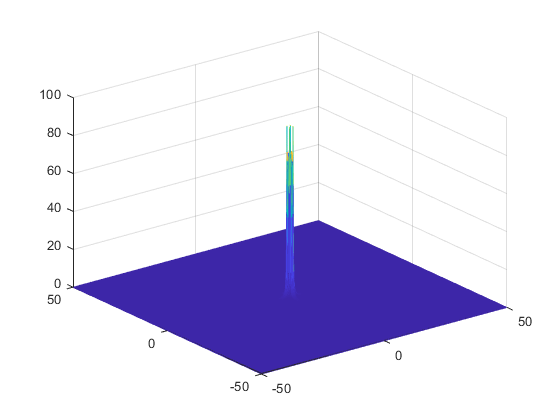

Ta =0.01;
x  = (-5:Ta:5);
y  = (-5:Ta:5);
w  = zeros(length(x),length(y));
N=length(x);
M=length(y);
f0= 1/(N*Ta);
fx = (0:(N-1))'*f0 - (N/2)*f0;
fy = (0:(M-1))'*f0 - (M/2)*f0;
for i = 1:length(y)
    w(:,i) = sin(2*pi.*sqrt((x.*x) + (y(i).*y(i))));
end
W = fftshift(fft2(w))/N;
mesh(fx,fy,abs(W));